%clear variables;

load('systems.mat');
system=system2;

% find exact position of starting bound minimum
x = [0 -1 0 -1 0 1];
x = find_minima(system, x);

tic;
eps_range = logspace(log10(1/200), log10(1/10), 5000);
mean_times = escape_statistics(system, x, eps_range, 10);
toc

Elapsed time is 65.562262 seconds.


fit_x = 1./eps_range; fit_y = log(mean_times);
%plot(fit_x, fit_y, 'x');

% Filter out the data that appears to be linear
fit_x = fit_x(1:15);
fit_y = fit_y(1:15);
%plot(fit_x, fit_y, 'x');

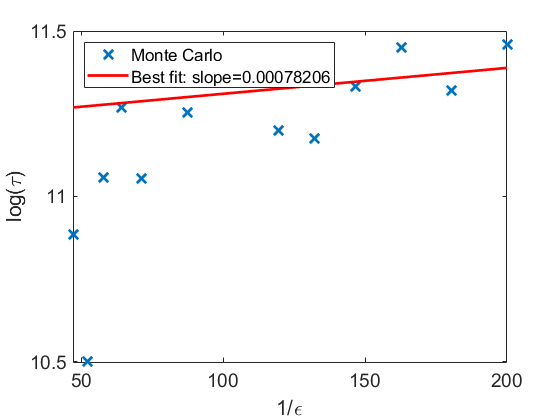

% Compute a linear fit, plot and extract the slope
p = polyfit(fit_x(1:10), fit_y(1:10), 1);
h = plot(fit_x, fit_y, 'x', fit_x, p(1)*fit_x+p(2),'r-', "LineWidth", 2, "MarkerSize", 10);
legend('Monte Carlo', ['Best fit: slope=' num2str(p(1))], 'Location', 'northwest')
xlabel('1/\epsilon'); ylabel('log(\tau)')
set(gca, "FontSize", 14)

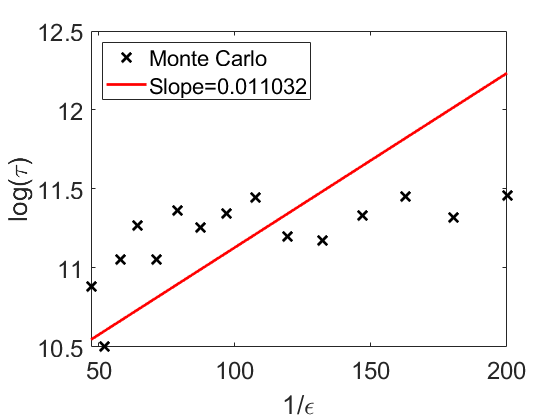

% Create a figure representing the quasipotential string (Note: must run
% figure 3 notebook first
load("data/stringmain_n_10_fe/output.mat");


[W,S,~,U] = compute_W(system2, out.x);

% choose height of line to agree with points
intercept = mean(fit_y) - S*mean(fit_x);

% Plot MC results with quasipotential slope
h = plot(fit_x, fit_y, 'kx', fit_x, S*fit_x+intercept,'r-', "LineWidth", 2, "MarkerSize", 10);
legend('Monte Carlo', ['Slope=' num2str(S)], 'Location', 'northwest')
xlabel('1/\epsilon'); ylabel('log(\tau)')
set(gca, "FontSize", 18)
saveas(gcf,'figures/5b.png')

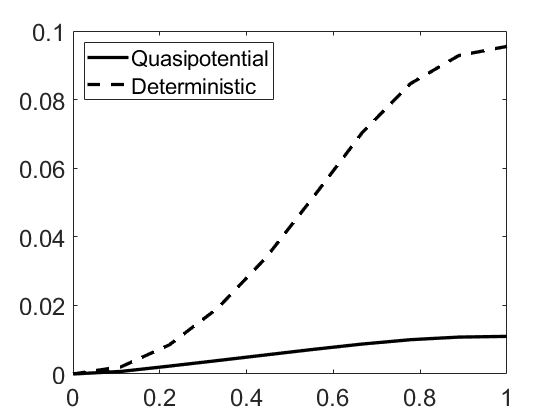


xx = linspace(0, 1, 10);
plot(xx, W, 'k', xx, U, 'k--', 'LineWidth', 2.5);
legend('Quasipotential', 'Deterministic', 'Location',"northwest")
set(gca, "FontSize", 18);
saveas(gcf,"figures/5a.png")